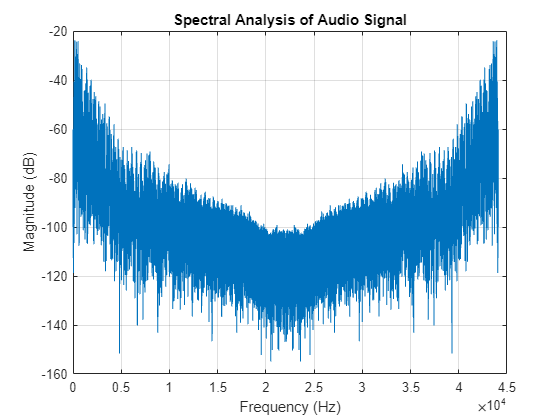

addpath('./lab1');
addpath('./lab2');
% Define the name of the WAV file
file_name = './lab2/musique.wav';
% Use the audioread function to read the WAV file
[audio_data, fs] = audioread(file_name);
% Perform the FFT on the audio data
N = length(audio_data);  % Length of the audio data
% Calculate the one-sided spectrum
[f, audio_spectrum]=transffourier(audio_data,N,fs);

% Plot the spectral analysis
figure;
plot(f, 20*log10(abs(audio_spectrum))); % Convert to decibels
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Spectral Analysis of Audio Signal');
grid on;

Note that an FFT result is mirrored (as in conjugate symmetric) only if the input data is real.

The sampling frequency is 44100
The quantization is 16 bits


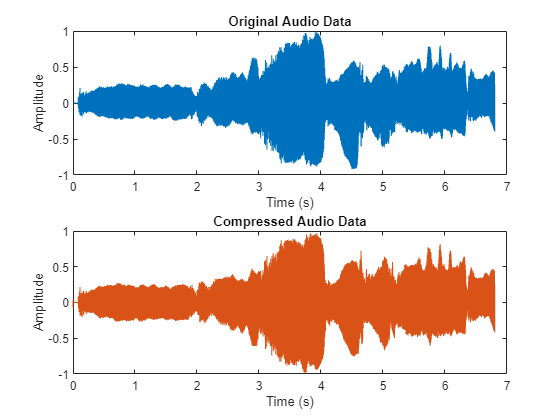

We acchived a compression of 275.5833%


% Define the name of the WAV file
file_name = './lab2/musique.wav';
fmin = 0;
fmax = 8000;

coderDecoder(file_name, fmin, fmax)

The sampling frequency is 44100
The quantization is 16 bits


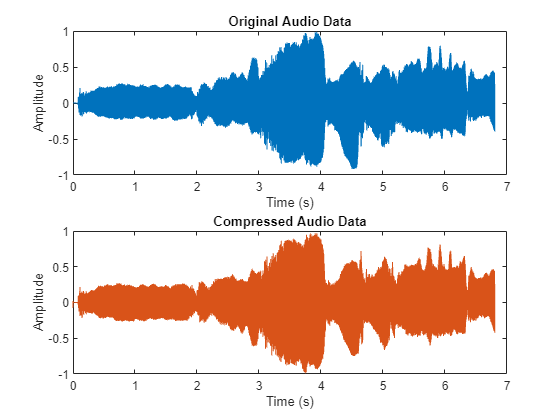

We acchived a compression of 279.0695%


% Define the name of the WAV file
file_name = './lab2/musique.wav';
fmin = 100;
fmax = 8000;

coderDecoder(file_name, fmin, fmax)

The sampling frequency is 44100
The quantization is 16 bits


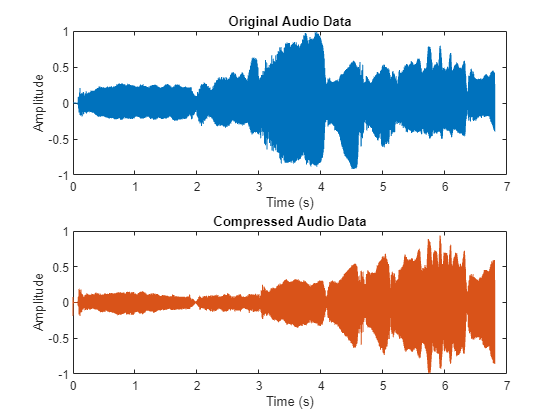

We acchived a compression of 314.944%


% Define the name of the WAV file
file_name = './lab2/musique.wav';
fmin = 1000;
fmax = 8000;

coderDecoder(file_name, fmin, fmax)

The sampling frequency is 44100
The quantization is 16 bits


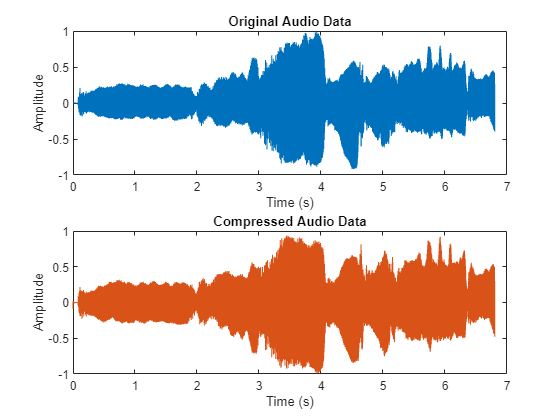

We acchived a compression of 324.2079%


% Define the name of the WAV file
file_name = './lab2/musique.wav';
fmin = 200;
fmax = 7000;

coderDecoder(file_name, fmin, fmax)